# Input:

tblh = readtable('O/Data/H.data', ...
    'Filetype', 'text', ...
    'ReadVariableNames',false);

tblh.Properties.VariableNames = {
    'Altitude', 'Latitude', 'Longitude', ...
    'PixelX', 'PixelY', 'Ylatitude'};
% , ...
    % 'ReadVariableNames',false
% tbl.Properties.VariableNames = {['' ...
    % 'PixelX'],'PixelY'};
% tbl.Ycoordinate = tbl.;

fprintf('Address: %s', ad)

Address: /MATLAB Drive/O/B o/0 GPS.txt

tblh(1:7,:)

ans = 7x6 table
        Altitude            Latitude            Longitude        PixelX    PixelY       Ylatitude    
    ________________    ________________    _________________    ______    ______    ________________

    120.753601074219    47.6414679277796    -122.140164908393       0         0      47.6414679277796
    222.535171508789    47.6374925258878    -122.140164908373     255       203      47.6374925258878
     224.43408203125    47.6374925270728    -122.140164908367     255       204      47.6374925270728
    224.434707641602    47.6374925270732    -122.140164908367     255       204      47.6374925270732
    224.739074707031    47.6374925272631    -122.140164908367     255       204      47.6374925272631
    225.413589477539    47.6374925276841    -122.140164908368    

% fread(fopen('/MATLAB Drive/Sir.txt', ...
%     'r'),'*char')'

# Display:

format long
% format shortG

% 47.6419266928565-la(1)
% 47.6419266928565-l(1)

% idx = randperm(100)
% save("id.mat","idx") % ,"q"

% save("id.mat","py","px","tltsa"
% ,"tltra", ...
%     "tlts","tltr","tla","tlltr","-append")

load("id.mat")
whos("-file","id.mat")

  Name        Size             Bytes  Class     Attributes

  idx         1x100              800  double              
  px          1x100              800  double              
  py         10x10               800  double              
  tla          -                6955  table               
  tlltr        -                5949  table               
  tllts        -                3069  table               
  tltr         -                5947  table               
  tltra        -                5951  table               
  tlts         -                3067  table               
  tltsa        -                3071  table               



% a(37:end)

# Latitude table:

tla = tblh(2:end, :);
fprintf(['Drone data, output: Latitude\n' ...
    '9 of 100 rows, 3 of 5 cols']);

Drone data, output: Latitude
9 of 100 rows, 3 of 5 cols

tla(2:10,:)

ans = 9x6 table
    Altitude    Latitude    Longitude    PixelX    PixelY    Ylatitude
    ________    ________    _________    ______    ______    _________

     224.43      47.637      -122.14      255       204       47.637  
     224.43      47.637      -122.14      255       204       47.637  
     224.74      47.637      -122.14      255       204       47.637  
     225.41      47.637      -122.14      255       204       47.637  
     226.08      47.637      -122.14      255       205       47.637  
     226.48      47.637      -122.14      255       205       47.637  
     227.05      47.637      -122.14      255       205       47.637  
     227.44      47.637      -122.14      255       206       47.637  
     227.86      47.637      -122.14      255       206       47.637 

% tla(65:67,:)

tltr = tla(sort(idx(21:100)),:);
tltr(2:10,[1 3 end])

ans = 9x3 table
    Altitude    Longitude    Ylatitude
    ________    _________    _________

     224.43      -122.14      47.637  
     224.74      -122.14      47.637  
     225.41      -122.14      47.637  
     226.48      -122.14      47.637  
     227.05      -122.14      47.637  
     227.44      -122.14      47.637  
     227.86      -122.14      47.637  
     228.97      -122.14      47.637  
     229.44      -122.14      47.637  


tlts = tla(sort(idx(1:20)),:);
tlts(2:10,[1 3 end])

ans = 9x3 table
    Altitude    Longitude    Ylatitude
    ________    _________    _________

     226.08      -122.14      47.637  
     228.46      -122.14      47.637  
        231      -122.14      47.637  
      233.9      -122.14      47.637  
     237.76      -122.14      47.637  
     238.76      -122.14      47.637  
     239.68      -122.14      47.637  
     240.19      -122.14      47.637  
     243.04      -122.14      47.637  


## Longitude table:

tl = tla

tl = 100x6 table
    Altitude    Latitude    Longitude    PixelX    PixelY    Ylatitude
    ________    ________    _________    ______    ______    _________

     222.54      47.637      -122.14      255       203       47.637  
     224.43      47.637      -122.14      255       204       47.637  
     224.43      47.637      -122.14      255       204       47.637  
     224.74      47.637      -122.14      255       204       47.637  
     225.41      47.637      -122.14      255       204       47.637  
     226.08      47.637      -122.14      255       205       47.637  
     226.48      47.637      -122.14      255       205       47.637  
     227.05      47.637      -122.14      255       205       47.637  
     227.44      47.637      -122.14      255       206       47.637

tl(:,"Ylatitude").Variables = tblh(1, ...
    3).Variables*ones(100,1);
tl.Properties.VariableNames{end} = ['' ...
    'Ylongitude'];
fprintf('Output: Longitude');tl(2:10,:)

Output: Longitude

ans = 9x6 table
    Altitude    Latitude    Longitude    PixelX    PixelY    Ylongitude
    ________    ________    _________    ______    ______    __________

     224.43      47.637      -122.14      255       204       -122.14  
     224.43      47.637      -122.14      255       204       -122.14  
     224.74      47.637      -122.14      255       204       -122.14  
     225.41      47.637      -122.14      255       204       -122.14  
     226.08      47.637      -122.14      255       205       -122.14  
     226.48      47.637      -122.14      255       205       -122.14  
     227.05      47.637      -122.14      255       205       -122.14  
     227.44      47.637      -122.14      255       206       -122.14  
     227.86      47.637      -122.14      255       206    

tlltr = tl(sort(idx(21:100)),:);
tlltr(2:10,[1 3 end])

ans = 9x3 table
    Altitude    Longitude    Ylongitude
    ________    _________    __________

     224.43      -122.14      -122.14  
     224.74      -122.14      -122.14  
     225.41      -122.14      -122.14  
     226.48      -122.14      -122.14  
     227.05      -122.14      -122.14  
     227.44      -122.14      -122.14  
     227.86      -122.14      -122.14  
     228.97      -122.14      -122.14  
     229.44      -122.14      -122.14  


tllts = tl(sort(idx(1:20)),:);
tllts(2:10,[1 3 end])

ans = 9x3 table
    Altitude    Longitude    Ylongitude
    ________    _________    __________

     226.08      -122.14      -122.14  
     228.46      -122.14      -122.14  
        231      -122.14      -122.14  
      233.9      -122.14      -122.14  
     237.76      -122.14      -122.14  
     238.76      -122.14      -122.14  
     239.68      -122.14      -122.14  
     240.19      -122.14      -122.14  
     243.04      -122.14      -122.14  


# Longitude gpr:

% cross-validation:
% rng('default') % For reproducibility
gprMdlo = fitrgp(tlltr, ...
    'Ylongitude', ...
    'KernelFunction', ...
    'ardsquaredexponential',...
      'FitMethod','sr','PredictMethod', ...
      'fic','Standardize',1,'Sigma',.002)

gprMdlo =   RegressionGP
           PredictorNames: {'Altitude'  'Latitude'  'Longitude'  'PixelX'  'PixelY'}
             ResponseName: 'Ylongitude'
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 80
           KernelFunction: 'ARDSquaredExponential'
        KernelInformation: [1x1 struct]
            BasisFunction: 'Constant'
                     Beta: -122.1402
                    Sigma: 0.0010
        PredictorLocation: [5x1 double]
           PredictorScale: [5x1 double]
                    Alpha: [80x1 double]
         ActiveSetVectors: [80x5 double]
            PredictMethod: 'FIC'
            ActiveSetSize: 80
                FitMethod: 'SR'
          ActiveSetMethod: 'Random'
        IsActiveSetVector: [80x1 logical]
            LogLikelihood: 479.1054
         ActiveSetHistory: [1x1 struct]
           BCDInformation: []


  Properties, <a hr

% ...
    %   'Standardize',1, ...
    % 'Sigma',.002)
% fprintf('kfoldLoss = %e', kfoldLoss( ...
%     cvgprMdl))
% ypred = kfoldPredict(cvgprMdl);
% fprintf('kfoldPredict: ');
% fprintf('%f\t', ypred')

ypredlo = predict(gprMdlo,tllts(:, ...
    1:end-1).Variables);ypredlo'

ans =  -122.1402 -122.1402 -122.1402 -122.1402 -122.1402 -122.1402 -122.1402 -122.1402 -122.1402 -122.1402 -122.1402 -122.1402 -122.1402 -122.1402 -122.1402 -122.1402 -122.1402 -122.1402 -122.1402 -122.1402


% elo = (lo(1)-ypredlo(1))/lo(1) %

% tlltr(1:20,"Ylongitude").Ylongitude

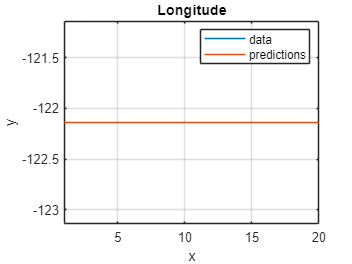

figure(); % ,'b.'
plot(tlltr(1:20,"Ylongitude").Ylongitude);
axis tight
xlabel('x')
ylabel('y')
hold on;
plot(ypredlo);
hold off;
grid on
legend({'data','predictions'}, ...
    'Location','Best');
title('Longitude')

# Laltitude gpr:

% cross-validation:
% rng('default') % For reproducibility
gprMdll = fitrgp(tltr, 'Ylatitude', ...
    'KernelFunction', ...
    'ardsquaredexponential',...
      'FitMethod','sr','PredictMethod', ...
      'fic','Standardize',1,'Sigma',.002)

gprMdll =   RegressionGP
           PredictorNames: {'Altitude'  'Latitude'  'Longitude'  'PixelX'  'PixelY'}
             ResponseName: 'Ylatitude'
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 80
           KernelFunction: 'ARDSquaredExponential'
        KernelInformation: [1x1 struct]
            BasisFunction: 'Constant'
                     Beta: 47.6375
                    Sigma: 0.0010
        PredictorLocation: [5x1 double]
           PredictorScale: [5x1 double]
                    Alpha: [80x1 double]
         ActiveSetVectors: [80x5 double]
            PredictMethod: 'FIC'
            ActiveSetSize: 80
                FitMethod: 'SR'
          ActiveSetMethod: 'Random'
        IsActiveSetVector: [80x1 logical]
            LogLikelihood: 479.1053
         ActiveSetHistory: [1x1 struct]
           BCDInformation: []


  Properties, <a href=

% ...
    %   'Standardize',1, ...
    % 'Sigma',.002)
% fprintf('kfoldLoss = %e', kfoldLoss( ...
%     cvgprMdl))
% ypred = kfoldPredict(cvgprMdl);
% fprintf('kfoldPredict: ');
% fprintf('%f\t', ypred')

ypredl = predict(gprMdll,tlts(:,1:end- ...
    1).Variables);ypredl'

ans =    47.6375   47.6375   47.6375   47.6375   47.6375   47.6375   47.6375   47.6375   47.6375   47.6375   47.6375   47.6375   47.6375   47.6375   47.6375   47.6375   47.6375   47.6375   47.6375   47.6375


% el = (l(1)-ypredl(1))/l(1)

[d1km, d2km] = lldistkm([tla(1, end ...
    ).Variables tlltr(1, end ...
    ).Variables], ...
    [ypredl(1) ypredlo(1)])

d1km = 1.8320e-06

d2km = 1.8320e-06

% d1km*1000 % m

ans = 0.0018

d1km*10^6 % mm

ans = 1.8320

% writetable(tla,['O/Data/5a H.' ...
%     'txt'],'Delimiter',' ') % All Car h a

% writetable(tl,'O/Data/5o H.txt',['' ...
%     'Delimiter'],' ') % Alll Car h a